## Initialize the simulator

simulator = Simulator();
%setup the victim's chirp parameters

simulator.load_B210_victim_params;
simulator.load_B210_attacker_params;

%apply timing offsets as desired
simulator.Victim.timing_offset_us = 0;
simulator.Attacker.timing_offset_us = 0;

%configure the FMCW parameters
simulator.configure_FMCW_parameters();

%load default target, attacker, and victim positions and velocities
simulator.load_target_realistic;
simulator.load_realistic_attacker_and_victim_position_and_velocity();

%print out key parameters
simulator.Victim.print_chirp_parameters;

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.20 MHz/us
	 Idle Time: 			 1.95 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.49 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 1.54 MSps
	 Ramp End Time: 		 48.05 us
	 Chirp Tx Bandwidth: 		 57.66 MHz
	 Chirp Sampling Bandwidth: 	 49.87 MHz
	 ADC Sampling Period: 		 41.56 us
	 Chirp Cycle Time: 		 50.00 us
	 Chirp Wavelength: 		 3.89 mm



simulator.Victim.print_frame_parameters;

Frame Parameters
	 Number of Chirps 		 32
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 1.60 ms


simulator.Victim.print_performance_specs;

Performance Specifications
	 Max Range 			 192.37 m
	 Range Resolution 		 3.01 m
	 Max Velocity 			 19.47 m/s
	 Velocity Resolution 		 1.22 m/s


simulator.Victim.print_FMCW_specs;

FMCW Specifications
	 FMCW sampling rate 		 58.52 MHz
	 Downsampling factor 		 38
	 Sweep time 			 48.05 us


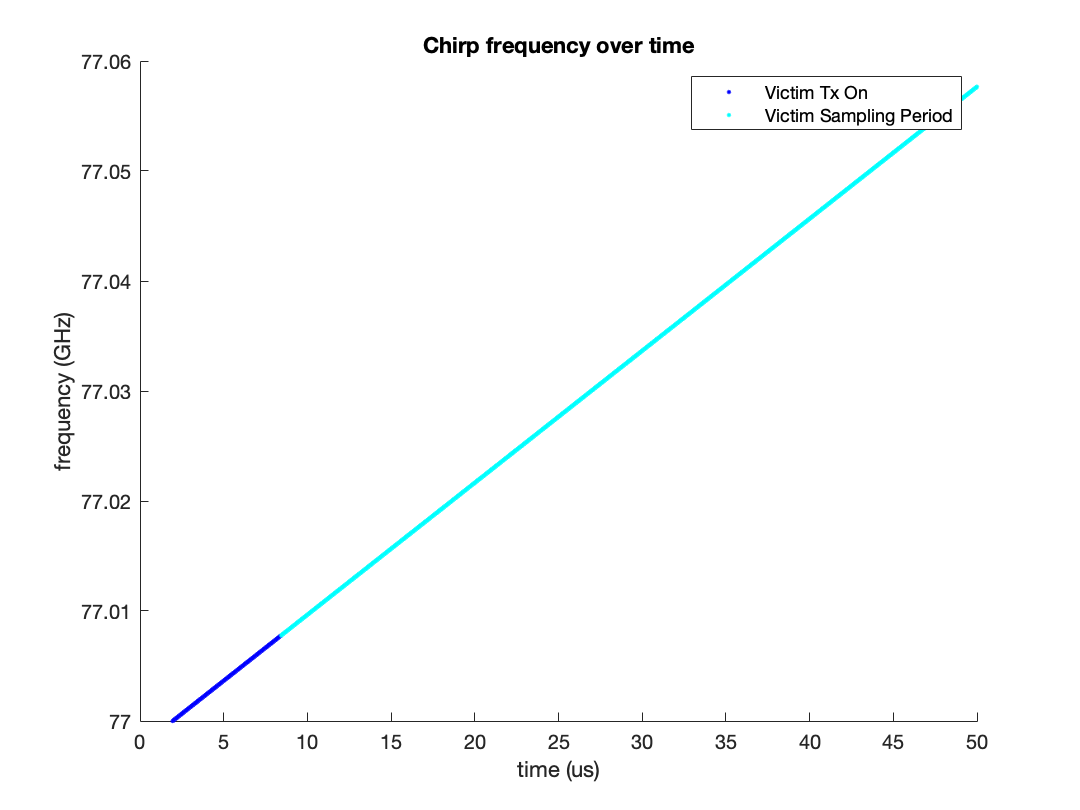

%simulator.Attacker.print_chirp_parameters;
%simulator.Attacker.print_frame_parameters;
%simulator.Attacker.print_performance_specs;
%simulator.Attacker.print_FMCW_specs;

Proof of concept for the attacker

%define the FMCW sampling period
FMCW_sampling_period = 1/simulator.Attacker.FMCW_sampling_rate_Hz;

%construct a new Attacker chirp that has been delayed
desired_range_m = 100;
desired_velocity_m_s = 15.0;


%declare variables needed for computing the attacker chirp parameters
simulator.Attacker.num_samples_idle_time = ...
    int32(simulator.Attacker.IdleTime_us ...
    * 1e-6 * simulator.Attacker.FMCW_sampling_rate_Hz);


t = 0:FMCW_sampling_period:simulator.Attacker.sweep_time - FMCW_sampling_period;

phase_shift_per_chirp = 4 * pi * desired_velocity_m_s * simulator.Attacker.ChirpCycleTime_us * 1e-6 / simulator.Attacker.Lambda_m;


Writing code to simulate the signal propogation through the signal processing chain

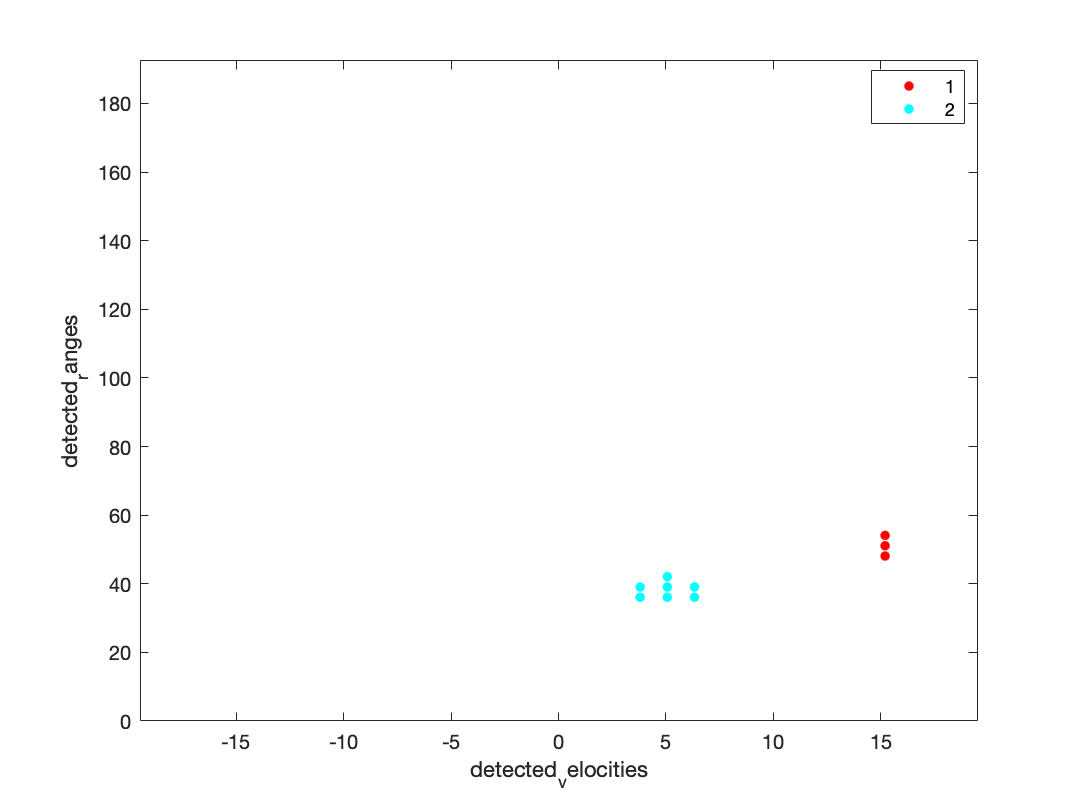

frames_to_compute = 100;

%configure it so that I can generate a movie
F_rngdop(frames_to_compute) = struct('cdata',[],'colormap',[]);
F_clusters(frames_to_compute) = struct('cdata',[],'colormap',[]);

for frame = int32(1:frames_to_compute)
% frame = 1;
    
    %initialize the array of chirps
    attacker_chirps = zeros(size(t,2) + simulator.Attacker.num_samples_idle_time, simulator.Attacker.NumChirps);

    %compute the location of the victim and the target
    [victim_pos, victim_vel,attacker_pos, attacker_vel, tgt_pos,tgt_vel] = simulator.FMCW_determine_positions_and_velocities(double(frame),1);    
    
    %generate the attacker chirps for the current frame
    %already existing time delay for propogation to the victim
    current_range = norm(pdist([attacker_pos.';victim_pos.']));
    propogation_delay = range2time(current_range,physconst('lightspeed'))/2;
    
    
    %time delay for range
    current_attack_range = desired_range_m - desired_velocity_m_s * ...
        simulator.Attacker.FramePeriodicity_ms * 1e-3 * ...
        (double(frame) - 1);
    desired_time_delay = range2time(current_attack_range,physconst('lightspeed'));
    additional_time_delay_needed = desired_time_delay - propogation_delay;
    num_samples_delay = additional_time_delay_needed / FMCW_sampling_period;
    
    for chirp = 1:simulator.Attacker.NumChirps
        %compute the phase shift
        phase_shift = (chirp - 1) * phase_shift_per_chirp;
    
        %compute the waveform
        waveform = cos(pi * simulator.Attacker.Chirp_Tx_Bandwidth_MHz * 1e6...
        / simulator.Attacker.sweep_time * t.^(2) + phase_shift) + ...
        1i * sin(pi * simulator.Attacker.Chirp_Tx_Bandwidth_MHz * 1e6...
        / simulator.Attacker.sweep_time * t.^(2) + phase_shift);
    
        %save it in the attacker_chirps array
        attacker_chirps(:,chirp) = [zeros(simulator.Attacker.num_samples_idle_time,1); waveform.'];
    
        if int32(num_samples_delay) > 0
            attacker_chirps(:,chirp) = ...
                [zeros(int32(num_samples_delay),1);...
                attacker_chirps(1: end - int32(num_samples_delay),chirp)];
        elseif num_samples_delay < 0
                    attacker_chirps(:,chirp) = ...
                    [attacker_chirps(int32(-1 * num_samples_delay) + 1: end,chirp);...
                    zeros(int32(-1 * num_samples_delay),1)];
        end
    end

    radar_cube = zeros(simulator.Victim.ADC_Samples,simulator.Victim.NumChirps);
    
    for chirp = int32(1:simulator.Victim.NumChirps)
    
        %generate the chirp
        FMCW_chirp = simulator.Victim.chirp;
        
        %send through the transmitter
        Tx_sig = simulator.Victim.transmitter(FMCW_chirp);
        
        %compute the location of all the victim, attacker, and target
        [victim_pos, victim_vel,attacker_pos, attacker_vel, tgt_pos,tgt_vel] = simulator.FMCW_determine_positions_and_velocities(double(frame),double(chirp));
        
        %propogate through the free-space channel
        
        free_space_sig = simulator.channel_target(Tx_sig,victim_pos,tgt_pos,victim_vel,tgt_vel);
        
        %reflect off of the target
        free_space_sig = simulator.SimulatedTarget.radar_target(free_space_sig);
        
        %add in the attacker
        attacker_sig = attacker_chirps(:,chirp);
        Tx_sig_attacker = simulator.Attacker.transmitter(attacker_sig);
        free_space_sig_attacker = simulator.channel_attacker(Tx_sig_attacker,attacker_pos,victim_pos,attacker_vel,victim_vel);

        %simulate the attack occurring after a specified number of frames
        if frame < 30
            combined_sig = free_space_sig;
        else
            combined_sig = free_space_sig + free_space_sig_attacker;
        end        
        
        %process the signal through the receiver
        Rx_sig = simulator.Victim.receiver(combined_sig);
        
        %dechirp and downsample the signal
        sampled_IF_sig = simulator.Victim.FMCW_simulate_dechirp_and_downsample(Tx_sig,Rx_sig);
        
        %assemble the radar cube
        radar_cube(:,chirp) = sampled_IF_sig;
    end
    
    %range-doppler response
    [resp, rnggrid,dopgrid] = simulator.Victim.RangeDopplerResponse(radar_cube);

    %plot the doppler response and sae it for a movie
    plotResponse(simulator.Victim.RangeDopplerResponse,radar_cube);
    drawnow
    F_rngdop(frame) = getframe(gcf);
    
    %CA CFAR 2-D
    detections = simulator.Victim.CFARDetector2D(abs(resp).^2,simulator.Victim.CUT_indicies);
    detected_velocities = dopgrid(detections(2,:));
    detected_ranges = rnggrid(detections(1,:));
    
    %DBSCAN Clustering
    idx = dbscan(detections.',simulator.Victim.Epsilon,simulator.Victim.minpts);

    %plot the clusters
    gscatter(detected_velocities,detected_ranges,idx);
    axis([-1 * simulator.Victim.V_Max_m_per_s, simulator.Victim.V_Max_m_per_s, 0,simulator.Victim.Range_Max_m]);
    drawnow
    F_clusters(frame) = getframe(gcf);
end

%play the movie for the range doppler
fig = figure;
movie(fig,F_rngdop,1,10)

%play the movie for the clusters
fig = figure;
movie(fig,F_clusters,1,10)

% %initialize other variables needed in the simulation
% victim_num_adc_samples = simulator.Victim.ADC_Samples;
% 
% open_system('FMCWSim');
% set_param('FMCWSim','StopTime','32 * simulator.Victim.sweep_time')